# Integral equations

## Taks 1

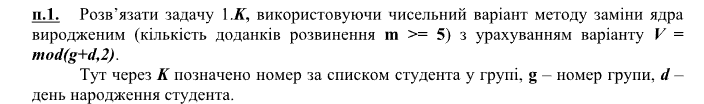

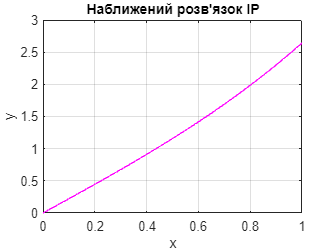

global m;
m = 6;

% kernel = @(x, t)((1 + t) * tan(2*x*t));

lambda = 1;
a = 0; b = 1;
n = 101;

[X,Y,n] = fr2_mzj(lambda, a, b, n, @fun1_k, @(x)(x));

plot(X,Y,'m'), title('Наближений розв''язок IP')
xlabel('x'), ylabel('y'), grid on;

## Taks 2

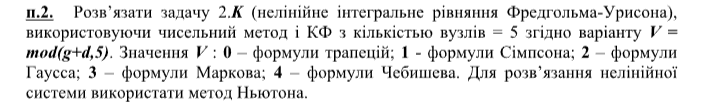

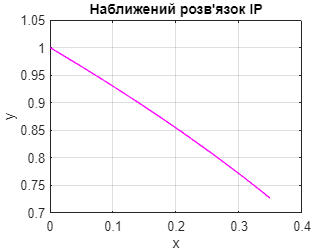

% test case
lambda = 1;
a = 0; b = 0.35;
n = 10; % we use Markov QD

eps = 1e-8; mi = 500;

Y = 0.05.*ones(n,1);
[X,Y] = frur_mk(a,b,n,@frurmk_k,@frurmk_f,Y,eps,mi);
plot(X,Y,'m'), title('Наближений розв''язок IP')
xlabel('x'), ylabel('y'), grid on

function [A,B] = fun1_k(x)
    A = [x, x^3/3, x^5/30, x^7/840, x^9/45360, x^11/3991680];
    B = [1, 1, x, x^2, x^3, x^4];
end


function [X, Y, n] = fr2_mzj(lambda, a, b, n, kfun, ffun)
    % Розв'язок лiнiйного неоднорiдного iнтегрального рiвняння
    % типу Фредгольма другого роду методом замiни ядра виродженим
    % b
    % y(x)=f(x)+lambda* ∫ K(x,s)*y(s)ds,
    % a
    % де K(x,s)=SUM(k=1,m,Ak(x)*Bk(s))
    % вхiднi данi :
    % lambda - числовий параметр рiвняння;
    % a - нижня границя iнтеграла;
    % b - верхня границя iнтеграла;
    % n - число точок сiтки
    % kfun - функцiя користувача, з описом ядра K(x,s);
    % ffun - функцiя користувача, з описом правої частини f(x);
    % вихiднi данi:
    % X - масив вузлiв сiтки;
    % Y - масив наближеного розв'язку;
    % n - розмірність масивiв X, Y.
    global m
    
    if n < 3
        n = 3;
    end

    if mod(n,2) == 0
        n = n + 1;
    end

    % формування вузлiв
    X = linspace(a, b, n); h = X(2) - X(1); n1 = n - 1;

    % формування коефiцiєнтiв P(i), i=1,...,n квадратурної формули
    P = zeros(n,1); FF = P; Y = P;
    P(1) = h ./ 3; c2 = 2 .* P(1); c1 = 2 .* c2;
    for i = 2 : 2 : n1
        P(i) = c1; P(i+1) = c2;
    end
    P(n) = P(1);

    % формування допомiжних матриць AK, BK i вектора FF,
    % де AK(k,i)=Ak(X(i)), BK(k,i)=Bk(X(i)),
    % FF(i)=f(X(i)), i=1,...,n.
    for i = 1 : n
        x = X(i);
        [AK(:, i), BK(:, i)] = kfun(x); FF(i) = ffun(x);
    end

    % формування матрицi A i вектора F СЛАР A*C=F,
    % де A(i,j)=if(i=j,1,0)-lambda*SUM(k=1,n, P(k)*AK(j,k)*BK(i,k) ),
    % F(i) =SUM(k=1,n, P(k)*FF(k)*BK(i,k) ), i=1,...,n
    F = zeros(m,1); A = zeros(m,m);
    for i = 1 : m
        for j = 1 : m
            aa = 0;
            for k = 1 : n
                aa = aa + P(k) .* AK(j, k) .* BK(i, k);
            end
            aa = -lambda .* aa;
            if i == j
                aa = 1 + aa;
            end
            A(i,j) = aa;
        end

        aa = 0;

        for k = 1 : n
            aa = aa + P(k) .* FF(k) .* BK(i, k);
        end
        F(i) = aa;
    end
    % розв'язок СЛАР A*C=F
    C = A\F;
    % розв'язок у виглядi
    % y(x)=f(x)+lambda * SUM(k=1, m, C(k) * Ak(x) )

    for i = 1 : n
        Y(i) = FF(i) + lambda .* dot(C, AK(:, i));
    end
end

function [y, yp] = frurmk_f(x,u)
    y = 1 - x - u^2;
    yp = -2*u;
end

function [y, yp] = frurmk_k(x, t, u)
    y = x;
    yp = 1;
end

function [X, Y] = frur_mk(a, b, n, k_dkfun, f_dffun, Y, e, mki)
    % Розв'язок нелiнiйного iнтегрального рiвняння
    % типу Фредгольма-Урисона методом замiни
    % iнтеграла скiнченною сумою
    % b
    % ∫ K(x,s,u(s))ds = f(x,u(x)), x є [a,b].
    % a
    % вхiднi данi :
    % a - нижня границя iнтеграла;
    % b - верхня границя iнтеграла;
    % k_dkfun - функцiя користувача, з описом ядра K(x,s,y)
    % i dK(x,s,u)/du;
    % f_dffun - функцiя користувача, з описом правої частини f(x,y)
    % i df(x,u)/du;
    % Y - початкове наближення до розв'язку;
    % e - точнiсть (e>0);
    % mki - максимальна кiлькiсть крокiв iтерацiй;
    % вихiднi данi:
    % X - масив вузлiв сiтки;
    % Y - масив наближеного розв'язку.

    % формування вузлiв сітки
    F = Y; J = zeros(n,n);
    % формування коефiцiєнтiв P(i), i=1,...,n
    % квадратурної формули
    P = ones(1, n);

    X = linspace(-1, 1, n);
    X(9) = 0.91953391; X(2) = - X(9); 
    X(8) = 0.73877386; X(3) = - X(8); 
    X(7) = 0.47792495; X(4) = - X(7); 
    X(6) = 0.16527896; X(5) = - X(6); 
    P(10) = 0.02222222; P(1) = P(10); 
    P(9) = 0.13330599; P(2) = P(9); 
    P(8) = 0.22488934; P(3) = P(8); 
    P(7) = 0.29204268; P(4) = P(7); 
    P(6) = 0.32753976; P(5) = P(6);
    % transform if [a, b] != [-1, 1]
    if a ~= -1 || b ~= 1        
        ab = 0.5 .* (a + b); ba = 0.5 .* (b - a); 
        for i = 1 : n 
            X(i) = ab + ba .* X(i);  P(i) = ba .* P(i); 
        end 
    end
    


    s = 0; Fl = 1;
    while Fl && s < mki
        % знаходження розв'язку нелінійної системи :
        % формування матрицi Якобі J i вектора F
        for i = 1:n
            xi = X(i); sk = 0;
            for j = 1:n
                p = P(j);
                [k,dk] = k_dkfun(xi,X(j),Y(j));
                J(i,j) = p.*dk; sk = sk + p.*k;
            end
            [f,df] = f_dffun(xi,Y(i));
            J(i,i) = J(i,i) - df;
            F(i) = sk - f;
        end

        d = J\F;

        Y = Y - d;
        s = s + 1;
        sk = norm(d);
        Fl = sk > e;
    end
    Y = abs(Y);
end
